## divide train set and test set

data = X_noout;
label = y_noout;
format short g

% rng(1); % For reproducibility
% cvp = cvpartition(y_noout, 'Holdout', 0.3)

## modified cars 

%vsels = [];

cvp = 留出交叉验证数据分区
   NumObservations: 599
       NumTestSets: 1
         TrainSize: 420
          TestSize: 179

%RMSECVs = [];

testnums = [50, 100, 200, 500, 1000];
vsel_best_m = zeros(length(effshift), length(testnums));
RMSECV_mins = zeros(1, length(testnums));
minRMSECVs = [];
num_vsel_cars = [];

for cc = 1:length(testnums)

    iternum = testnums(cc);
    RMSECV_min = 1;
    vsel_best = 1:length(effshift);

    for i = 1:iternum
        Cars = feature_cars(data(training(cvp), :),...
            label(training(cvp)), 7, 5, 'center', 100, i);

        vsel_incre = Cars.vsel;
        minRMSECV_incre = Cars.minRMSECV;
        %RMSECV_incre = Cars.RMSECV;

        %vsels = [vsels, vsel_incre];
        %RMSECVs = [RMSECVs, RMSECV_incre];
        minRMSECVs = [minRMSECVs, minRMSECV_incre];
        num_vsel_cars = [num_vsel_cars, length(vsel_incre)];

        if length(vsel_incre) < length(vsel_best)
            if  minRMSECV_incre <= RMSECV_min + 0.05

                RMSECV_min = minRMSECV_incre;
                vsel_best = vsel_incre;

            end
        end
    end

    fprintf('The %d try finished.\n', iternum)
    fprintf('RMSECV_min = %.6f \n', RMSECV_min)
    vsel_best

    RMSECV_mins(cc) = RMSECV_min;
    vsel_best_00 = [vsel_best, zeros(1, length(effshift)-length(vsel_best))];
    vsel_best_m(:, cc) = vsel_best_00;

end

The 50 try finished.


RMSECV_min = 0.393977 


vsel_best =     18    22    23    40    42   232   233   234   260   290   304   319   328


The 100 try finished.


RMSECV_min = 0.393977 


vsel_best =     18    22    23    40    42   232   233   234   260   290   304   319   328


The 200 try finished.


RMSECV_min = 0.393977 


vsel_best =     18    22    23    40    42   232   233   234   260   290   304   319   328


The 500 try finished.


RMSECV_min = 0.395712 


vsel_best =     18    22    23    24    40   232   233   234   260   304   319   328


The 1000 try finished.


RMSECV_min = 0.395712 


vsel_best =     18    22    23    24    40   232   233   234   260   304   319   328


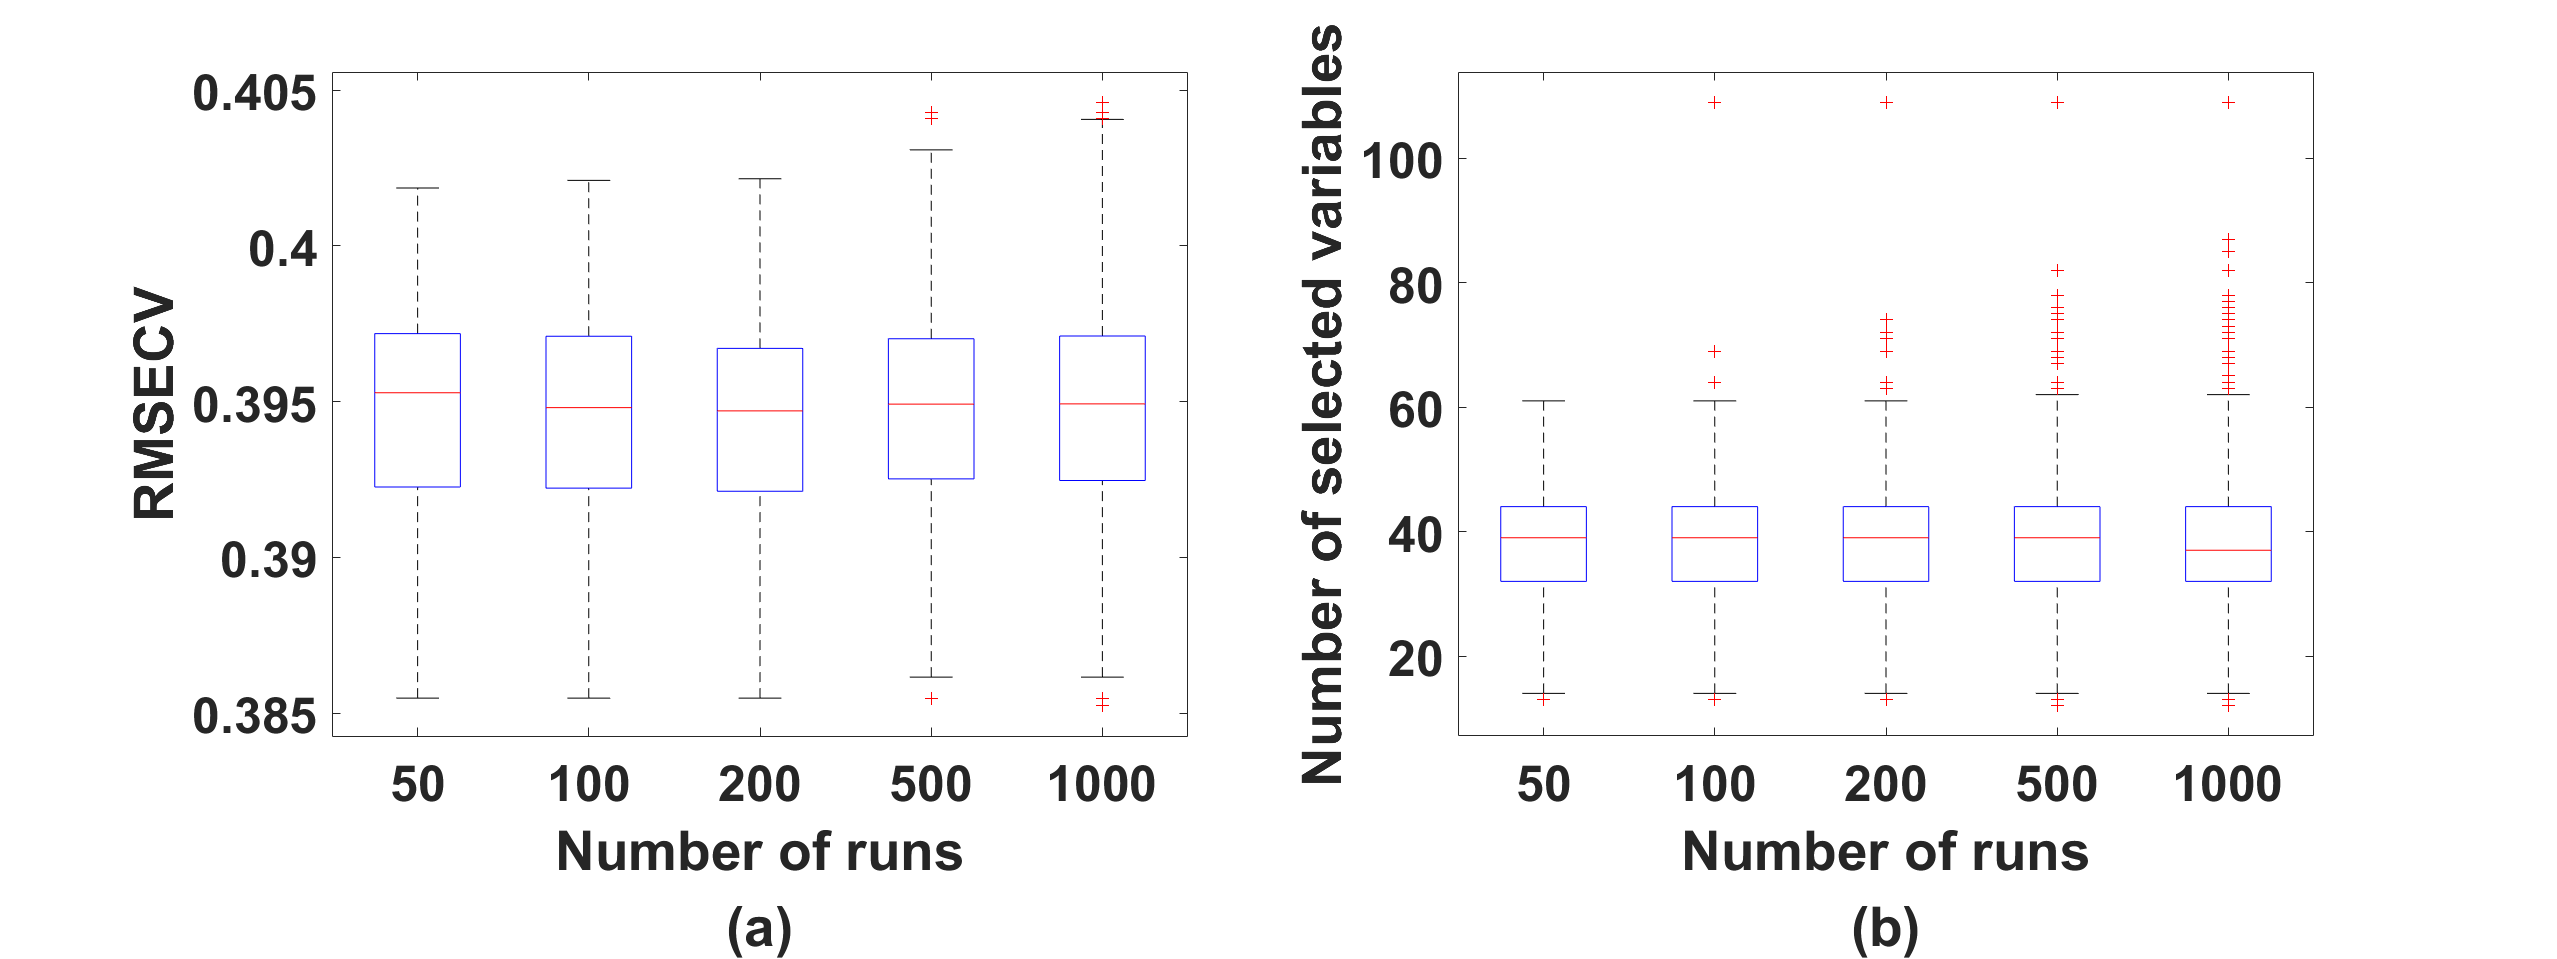

testnums0 = [1000, 2000];

for cc = 1:length(testnums0)

    iternum = testnums0(cc);
    RMSECV_min = 1;
    vsel_best = 1:length(effshift);

    for i = 1:iternum
        Cars = feature_cars(data(training(cvp), :),...
            label(training(cvp)), 7, 5, 'center', 100, i);

        vsel_incre = Cars.vsel;
        minRMSECV_incre = Cars.minRMSECV;
        %RMSECV_incre = Cars.RMSECV;

        %vsels = [vsels, vsel_incre];
        %RMSECVs = [RMSECVs, RMSECV_incre];
        minRMSECVs = [minRMSECVs, minRMSECV_incre];
        num_vsel_cars = [num_vsel_cars, length(vsel_incre)];


        if length(vsel_incre) < length(vsel_best)
            if  minRMSECV_incre <= RMSECV_min + 0.05

RMSECV_mins =       0.39398      0.39398      0.39398      0.39571      0.39571


vsel_best_m =     18    18    18    18    18
    22    22    22    22    22
    23    23    23    23    23
    40    40    40    24    24
    42    42    42    40    40
   232   232   232   232   232
   233   233   233   233   233
   234   234   234   234   234
   260   260   260   260   260
   290   290   290   304   304


                RMSECV_min = minRMSECV_incre;
                vsel_best = vsel_incre;

ans =        469.23        485.2       489.19       556.63       564.52       1275.1       1278.7       1282.2       1373.7       1477.6       1525.6       1576.5       1606.9



            end
        end
    end

    fprintf('The %d try finished.\n', iternum)
    fprintf('RMSECV_min = %.6f \n', RMSECV_min)
    vsel_best

    RMSECV_mins = [RMSECV_mins, RMSECV_min];
    vsel_best_00 = [vsel_best, zeros(1, length(effshift)-length(vsel_best))];
    vsel_best_m = [vsel_best_m, vsel_best_00];

end

testnums_s = testnums;
group_cars = [];

for cc = 1:length(testnums_s)
    group_cars = [group_cars, repmat(testnums_s(cc), 1, testnums_s(cc))];
end

%boxplot of rmse and vsel num
figure('Units','normalized', 'Position', [0, 0, 1, 0.6]);

subplot(1,2,1)
boxplot(minRMSECVs, group_cars)
xlabel({'Number of runs', '(a)'}, "FontSize", 20);
ylabel('RMSECV', "FontSize", 20);
set(gca,'fontsize',25, 'FontWeight','bold');

subplot(1,2,2)
boxplot(num_vsel_cars, group_cars)
xlabel({'Number of runs', '(b)'}, "FontSize", 20);
ylabel('Number of selected variables', "FontSize", 20);
set(gca,'fontsize',25, 'FontWeight','bold');

RMSECV_mins
vsel_best_m

effshift(vsel_best)

*
optimization finished, #iter = 37
nu = 0.135993
obj = -51.838847, rho = 0.232522
nSV = 26, nBSV = 20
*
optimization finished, #iter = 44
nu = 0.266289
obj = -126.033112, rho = 0.097395
nSV = 49, nBSV = 43
*
optimization finished, #iter = 20
nu = 0.068654
obj = -27.249810, rho = 0.104555
nSV = 13, nBSV = 9
*
optimization finished, #iter = 44
nu = 0.247997
obj = -111.403622, rho = -0.178537
nSV = 43, nBSV = 39
*
optimization finished, #iter = 43
nu = 0.077380
obj = -33.344106, rho = 0.217025
nSV = 16, nBSV = 11
*
optimization finished, #iter = 67
nu = 0.296991
obj = -142.006763, rho = 0.826217
nSV = 53, nBSV = 46
Total nSV = 137
*
optimization finished, #iter = 62
nu = 0.139125
obj = -52.858811, rho = 0.513043
nSV = 27, nBSV = 20
*
optimization finished, #iter = 76
nu = 0.279002
obj = -131.941944, rho = 0.194455
nSV = 51, nBSV = 44
*
optimization finished, #iter = 33
nu = 0.091172
obj = -37.905685, rho = 0.685590
nSV = 17, nBSV = 13
*
optimization finished, #iter = 53
nu = 0.251242
obj

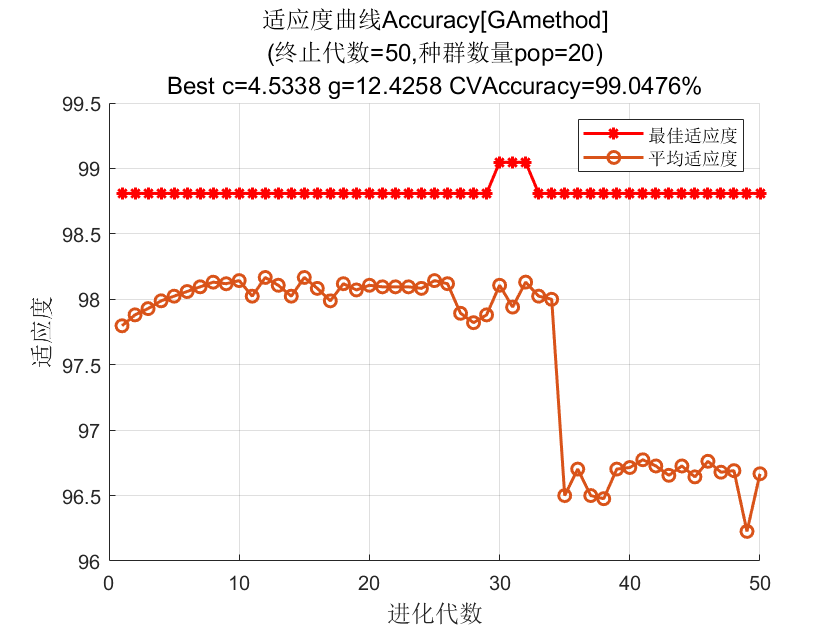

% freqs = [];

% 

历时 20.921465 秒。


% for j = 1:length(effshift)
%     freq = sum(vsels == j);
%     freqs = [freqs, freq];
% end
% 
% vsel = find(freqs >= floor(iternum * 0.5))
% effshift(vsel)
% 

*
optimization finished, #iter = 93
nu = 0.041963
obj = -21.340744, rho = 0.328001
nSV = 18, nBSV = 4
*
optimization finished, #iter = 59
nu = 0.121462
obj = -65.523745, rho = 0.176553
nSV = 29, nBSV = 20
*
optimization finished, #iter = 58
nu = 0.032635
obj = -16.801532, rho = -0.002406
nSV = 12, nBSV = 4
*
optimization finished, #iter = 119
nu = 0.105383
obj = -59.181478, rho = 0.003794
nSV = 29, nBSV = 16
*
optimization finished, #iter = 44
nu = 0.036963
obj = -19.719894, rho = -0.083588
nSV = 16, nBSV = 5
*
optimization finished, #iter = 82
nu = 0.149219
obj = -98.534495, rho = 1.013564
nSV = 35, nBSV = 28
Total nSV = 97


% CV = plscvfold(data(training(cvp), vsel), label(training(cvp)), 7);  
%    
% CV.RMSE_min

Accuracy = 99.2857% (417/420) (classification)


% CV.Rsquare_max     


Accuracy = 100% (179/179) (classification)


## vsel_best

data = X_noout;
label = y_noout;

vsel_best = vsel_best_m(1:13, 3);
train_data  = data(training(cvp), vsel_best);

Accuracy = 96.875% (155/160) (classification)


train_label = label(training(cvp));
test_data   = data(test(cvp), vsel_best);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);

tic
[~, bestc, bestg] = gaSVMcgForClass(train_label, train_data);
toc

% vsel_best
s = 0;
t = 2;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);
[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

valid_data = X_valid_noout(:, vsel_best);
valid_label = y_valid_noout;

[~, valid_acc, ~]...
    = libsvmpredict(valid_label, valid_data, model);

## confusion matrix

% plotconfusion(test_label.', test_pred_label.');

# model = libsvmtrain(label, data, ‘option’)

# [predicted_label, accuracy,decision_values] = libsvmpredict(y_test, x_test, model)

% options:
% -s svm_type : set type of SVM (default 0)
% 	0 -- C-SVC		(multi-class classification)
% 	1 -- nu-SVC		(multi-class classification)
% 	2 -- one-class SVM
% 	3 -- epsilon-SVR	(regression)
% 	4 -- nu-SVR		(regression)
% -t kernel_type : set type of kernel function (default 2)
% 	0 -- linear: u'*v
% 	1 -- polynomial: (gamma*u'*v + coef0)^degree
% 	2 -- radial basis function: exp(-gamma*|u-v|^2)
% 	3 -- sigmoid: tanh(gamma*u'*v + coef0)
% 	4 -- precomputed kernel (kernel values in training_set_file)
% -d degree : set degree in kernel function (default 3)
% -g gamma : set gamma in kernel function (default 1/num_features)  
%            gamma越大，支持向量越少，过拟合
% -r coef0 : set coef0 in kernel function (default 0)
% -c cost : set the parameter C of C-SVC, epsilon-SVR, and nu-SVR (default 1)
%           C是惩罚系数（正则化参数的倒数），即对误差的宽容度，c越大，容易过拟合
% -n nu : set the parameter nu of nu-SVC, one-class SVM, and nu-SVR (default 0.5)
% -p epsilon : set the epsilon in loss function of epsilon-SVR (default 0.1)
% -m cachesize : set cache memory size in MB (default 100)
% -e epsilon : set tolerance of termination criterion (default 0.001)
% -h shrinking : whether to use the shrinking heuristics, 0 or 1 (default 1)
% -b probability_estimates : whether to train a SVC or SVR model for probability estimates, 0 or 1 (default 0)
% -wi weight : set the parameter C of class i to weight*C, for C-SVC (default 1)
% -v n: n-fold cross validation mode(default 5)
% -q : quiet mode (no outputs)

% iter为迭代次数，
% nu 与前面的操作参数-n nu 相同，
% obj为SVM文件转换为的二次规划求解得到的最小值，
% rho 为判决函数的常数项b，
% nSV 为支持向量个数，
% nBSV为边界上的支持向量个数，
% Total nSV为支持向量总个数。
% 训练后的模型保存为文件*.model，用记事本打开其内容如下：
% svm_type c_svc % 训练所采用的svm类型，此处为C- SVC
% kernel_type rbf %训练采用的核函数类型，此处为RBF核
% gamma 0.0769231 %设置核函数中的g ，默认值为1/ k
% nr_class 2 %分类时的类别数，此处为两分类问题
% total_sv 132 %总共的支持向量个数
% rho 0.424462 %决策函数中的常数项b
% label 1 -1%类别标签
% nr_sv 64 68 %各类别标签对应的支持向量个数